## State space model of a buck converter

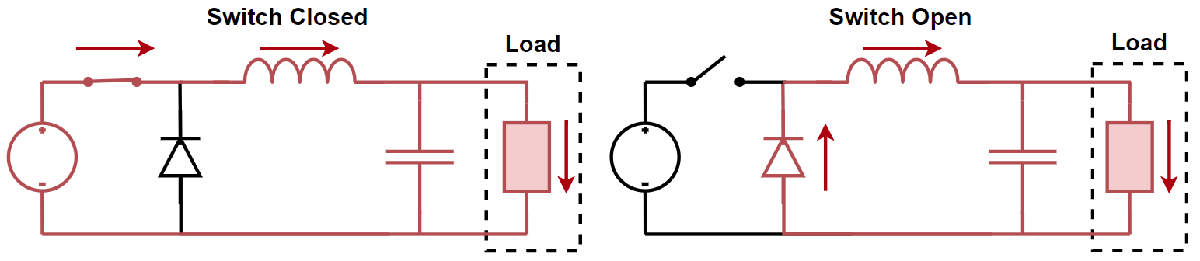

clc;
clear

% % System variables ---------------------------------------------------------------

R = 100;        % Load Resistor
L = 4.1e-3;     % Inductor
C = 10e-6;      % Capacitor
V_i = 12;       % Input Voltage

% % Set the desired outputs --------------------------------------------------------

V_o = 6;        % Desired output voltage
duty = V_o/V_i; % Duty cycle calculation

% % State matrecies ----------------------------------------------------------------

A = [-1/(R*C), 1/C;
    -1/L,     0];

B = [0,V_i/L]';

C = [1, 0];

D = [];

% % System Simulation -------------------------------------------------------------

sys = ss(A, B, C, D);      % Create the system model

t = 0:0.005/100:0.5;       % Setup the times series
u = zeros(length(t),1);    % Setup the input vector
u(t>0.005) = duty/2;         % Generate step input of the duty cycle
u(t>0.25) = duty;         % Generate step input of the duty cycle
x_0 = [0, 0, 0]';          % Set initial conditions to zero

[controller, ~] = pidtune(sys, "PI", 3000);
sys_controlled = feedback(controller*sys, 1/V_i);
info = stepinfo(sys_controlled)

info = struct with fields:
        RiseTime: 0.0136
    SettlingTime: 0.0242
     SettlingMin: 10.8480
     SettlingMax: 11.9997
       Overshoot: 0
      Undershoot: 0
            Peak: 11.9997
        PeakTime: 0.0653


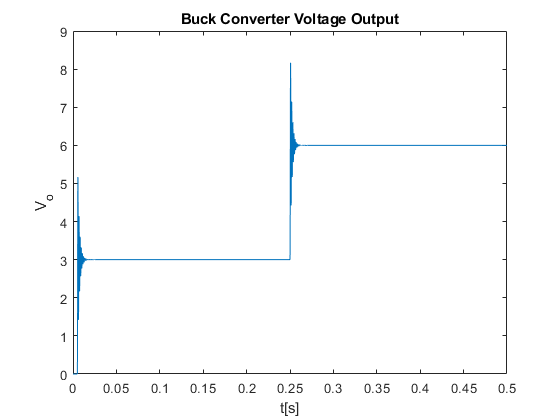


[y, t, x] = lsim(sys, u, t, []);
[y_controlled, t_controlled, x_controlled] = lsim(sys_controlled, u, t, []);

figure()
plot(t, y);
title("Buck Converter Voltage Output");
xlabel('t[s]');
ylabel('V_o');
ylim([0 9])

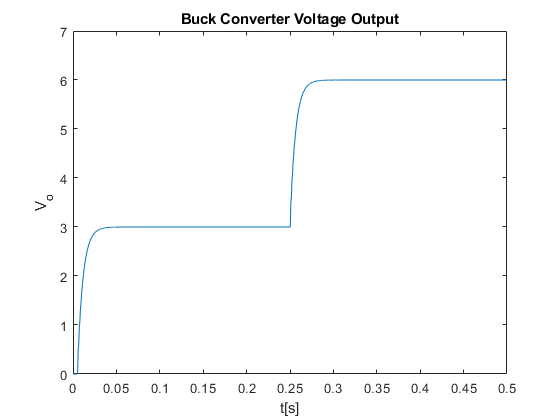


figure()
plot(t_controlled, y_controlled);
title("Buck Converter Voltage Output");
xlabel('t[s]');
ylabel('V_o');
ylim([0 7])